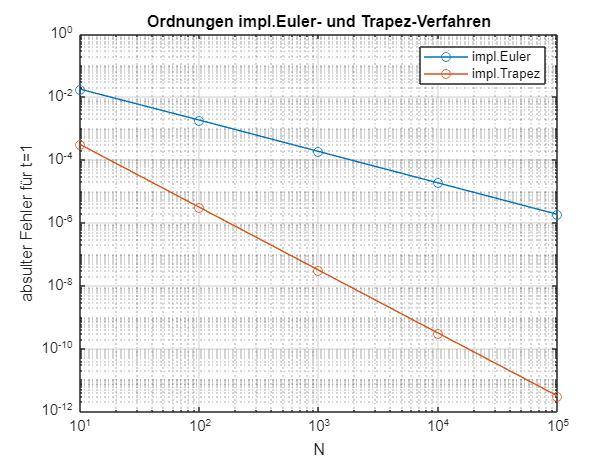

% die Funktion und ihre Ableitung definieren
func = @(t,y) -y;
dfunc = @(t,y) -1;

% die exakte Lösung
func_loes = @(x) exp(-x);

y_a = 1; % Anfangsbedingung 
t_span = [0,1]; % Intervall
tol = 10^-6; % Toleranz
N = 10.^(1:5); % Anzahl von Teilintervallen
nmax = 100; % maximale Anzahl an Schritten des Newton-Verfahrens


Abs_err_max_Euler = max_abs_error(@(N) impl_euler(func ,t_span ,y_a ,N ,dfunc, tol, nmax), func_loes, N);
Abs_err_max_Trapez = max_abs_error(@(N) impl_trapez(func ,t_span ,y_a ,N ,dfunc, tol, nmax), func_loes, N);

loglog(N,Abs_err_max_Euler,'o-','DisplayName','impl.Euler');
title('Ordnungen impl.Euler- und Trapez-Verfahren')
xlabel("N");
ylabel('absulter Fehler für t=1')
set(gca,'FontSize',10)
legend
grid on


hold on
loglog(N,Abs_err_max_Trapez,'o-','DisplayName','impl.Trapez')